%パラメータ設定
numNode = 100; %ノード数
completeGraph = complete_graph(numNode); %N_node個のノードを持つ完全グラフ
adjacencyMatrix = adjacency(completeGraph); %completeGraphの隣接行列
omega = 3; %固有振動数
dencityBetweenNodes = 8; %ノード間の結合密度
p = 0:0.01:1; %不活性ノードの割合
activeNode = 1; %活性ノードの自己振幅係数
inactiveNode = -1; %不活性ノードの自己振幅係数
t_max = 60;
dt = 0.05;
t_steps = t_max/dt;
t = 0:dt:t_max - dt;
ntrans = 600;
z_abs_dataA = nan(1, length(p)); %zの平均振幅を格納するNaN配列
z_initial = ones(numNode, 1) + 1i * zeros(numNode, 1); %初期値 1 + 0*i
z_initial = [real(z_initial); imag(z_initial)]';
dim = numNode*2;

% 数式計算
parfor j = 1:length(p)
   disp(p(j))
   z_dataA = solve_model(t_steps, ntrans, dim, t, p(j), numNode, ...
    activeNode, inactiveNode, z_initial, omega, dencityBetweenNodes, adjacencyMatrix);

   % 実部と虚部を取り出して複素数に戻す
   real_partA = z_dataA(:, 1:2:end); % 偶数番目が実部
   imag_partA = z_dataA(:, 2:2:end); % 奇数番目が虚部  
   
   % 複素数形式に再構築
   z_data_mergeA = real_partA + 1i * imag_partA;

   % 振幅の平均を計算
   z_amplitudeA = mean(abs(z_data_mergeA), 2);
   z_abs_dataA(:, j) = z_amplitudeA(end);
end

    0.0500

    0.0100

    0.0300

    0.0700

    0.0400

     0

    0.0200

    0.0600

    0.1900

    0.4300

    0.3100

    0.5500

    0.4200

    0.1800

    0.3000

    0.1700

    0.5400

    0.4100

    0.5300

    0.2900

    0.4000

    0.1600

    0.2800

    0.5200

    0.3900

    0.1500

    0.2700

    0.5100

    0.3800

    0.1400

    0.2600

    0.5000

    0.3700

    0.3600

    0.4900

    0.4800

    0.1300

    0.2500

    0.3500

    0.3400

    0.1200

    0.2400

    0.4700

    0.1100

    0.2300

    0.4600

    0.3300

    0.1000

    0.2200

    0.4500

    0.2100

    0.4400

    0.3200

    0.0900

    0.2000

    0.6700

    0.6600

    0.0800

    0.7900

    0.7800

    0.6500

    0.7300

    0.7200

    0.7700

    0.6400

    0.6100

    0.6000

    0.7100

    0.7600

    0.6300

    0.5900

    0.7000

    0.7500

    0.6200

    0.6900

    0.7400

    0.8500

    0.8400

    0.5800

    0.6800

    0.8200

    0.8100

    0.8300

    0.57

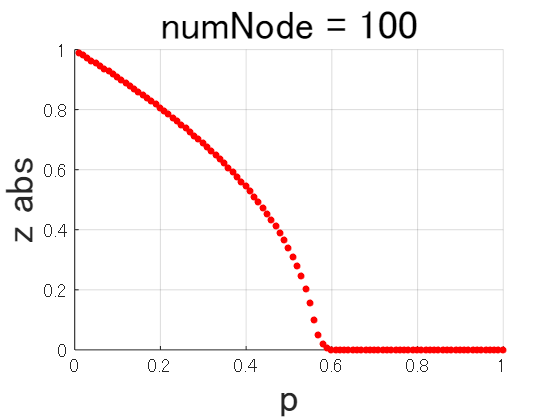

% 可視化
filename = 'plotFile/real_data_birfication.pdf';
% タイトルにnumNodeを含める
titleText = sprintf('numNode = %d', numNode);

figure;
scatter(p, z_abs_dataA, 10, 'red', 'filled'); % -oでデータポイントをプロット
title(titleText, 'FontSize', 18);
xlabel('p', 'FontSize', 18);
ylabel('z abs', 'FontSize', 18);
grid on;
ylim([0 1]);

%set(gca, 'FontSize', 14);
% プロットをPDFに保存
%exportgraphics(gcf, filename, 'Append', true); % 'Append'でPDFに追加
% close(gcf); % 図を閉じる

filename = 'resources/data.txt';

% ファイルの存在をチェック
if ~isfile(filename)
    % ファイルが存在しない場合、新規作成
    disp(['ファイル ', filename, ' は存在しません。新規作成します。']);
    fclose(fopen(filename, 'w')); % 空のファイルを作成
else
    disp(['ファイル ', filename, ' が既に存在します。データを追記します。']);
end

ファイル resources/data.txt が既に存在します。データを追記します。



dlmwrite(filename, z_abs_dataA, '-append', 'delimiter', '\t');

disp(['データが ', filename, ' に保存されました']);

データが resources/data.txt に保存されました
